# **Week L0: Single-Carrier with Alamouti Coding**

This script implements a simplified optic fibre communications system using Alamouti coding

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using QPSK and 16-QAM

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser according to an electrical signal

### Alamouti Coding

clear all; clearvars;

% Parameters
NSymb = 400000; % No. of symbols 
SpS = 1; % Samples per symbol
Rs = 20e9; % Symbol rate in symbols/sec
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevelsQPSK = [asin(-1/sqrt(2)), asin(1/sqrt(2))]'; % Discrete voltages for QAM
voltageLevelsQAM = [asin(-3/sqrt(10)), asin(-1/sqrt(10)), asin(1/sqrt(10)), asin(3/sqrt(10))]';
DCOffset = 0; % DC offset of modulated current in V

% --------------------------------------------------------------------------------------

% FOR QPSK:
% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, 1); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4); % Maps source bit vector to symbol vector
codedSymbolsQPSK = AlamoutiCoding(sourceSymbolsQPSK); % Encodes symbols using Alamouti coding

% Modulating voltage with generated symbols
vI_QPSK = ones(size(codedSymbolsQPSK)); vQ_QPSK = zeros(size(codedSymbolsQPSK));

vI_QPSK(real(codedSymbolsQPSK)>0) = voltageLevelsQPSK(2); % Maps 1 -> asin(1/sqrt(2))
vI_QPSK(real(codedSymbolsQPSK)<0) = voltageLevelsQPSK(1); % Maps -1 -> asin(-1/sqrt(2))
vQ_QPSK(imag(codedSymbolsQPSK)>0) = voltageLevelsQPSK(2); % Maps 1 -> asin(1/sqrt(2))
vQ_QPSK(imag(codedSymbolsQPSK)<0) = voltageLevelsQPSK(1); % Maps -1 -> asin(-1/sqrt(2))

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
% stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1), "o-");
% title("Modulated Voltage for QPSK")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

% -----------------------------------------

% For 16QAM
sourceBitsQAM = randi([0 1], NSymb*4, 1); % Matrix of source bits for 16QAM
sourceIntsQAM = bit2int(sourceBitsQAM, 4); % Vector of source bits converted to ints
sourceSymbolsQAM = qammod(sourceIntsQAM, 16, UnitAveragePower=true); % Maps source bit vector to symbol vector
codedSymbolsQAM = AlamoutiCoding(sourceSymbolsQAM);  % Encodes symbols using Alamouti coding

% Modulating voltage with generated symbols
vI_QAM = ones(size(codedSymbolsQAM)); vQ_QAM = zeros(size(codedSymbolsQAM));

QAMBoundaries = [-2/sqrt(10), 0, 2/sqrt(10)];

vI_QAM(real(codedSymbolsQAM)<=-2/sqrt(10)) = voltageLevelsQAM(1); 
vI_QAM(real(codedSymbolsQAM)>-2/sqrt(10) & real(codedSymbolsQAM)<=0) = voltageLevelsQAM(2);
vI_QAM(real(codedSymbolsQAM)>0 & real(codedSymbolsQAM)<=2/sqrt(10)) = voltageLevelsQAM(3); 
vI_QAM(real(codedSymbolsQAM)>2/sqrt(10)) = voltageLevelsQAM(4); 

vQ_QAM(imag(codedSymbolsQAM)<=-2/sqrt(10)) = voltageLevelsQAM(1); 
vQ_QAM(imag(codedSymbolsQAM)>-2/sqrt(10) & imag(codedSymbolsQAM)<=0) = voltageLevelsQAM(2);
vQ_QAM(imag(codedSymbolsQAM)>0 & imag(codedSymbolsQAM)<=2/sqrt(10)) = voltageLevelsQAM(3); 
vQ_QAM(imag(codedSymbolsQAM)>2/sqrt(10)) = voltageLevelsQAM(4); 

vI_QAM_upsampled = repelem(vI_QAM, SpS, 1); % Upsampling according to SpS
vQ_QAM_upsampled = repelem(vQ_QAM, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
% stairs(t(1:10*SpS), vI_QAM_upsampled(1:10*SpS,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_QAM_upsampled(1:10*SpS,1), "o-");
% title("Modulated Voltage for 16QAM")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

### Pulse Shaping

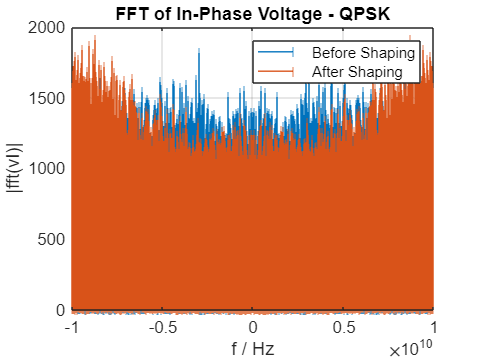

% RRC filter parameters
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");

% stem(filterResponse_t, filterResponse, '-o');
% title('Impulse Response of RRC Filter');
% xlabel('Time / s');
% ylabel('Normalised Amplitude');
% grid on

% ---------------------------------------------------------------------------

% FOR QPSK:
% Using RRC filter to shape vI and vQ

vI_QPSK_shaped = upfirdn(vI_QPSK, filterResponse, SpS, 1); vQ_QPSK_shaped = upfirdn(vQ_QPSK, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QPSK = fftshift(fft(vI_QPSK_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QPSK_shaped = fftshift(fft(vI_QPSK_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

% stem(freqArr, abs(fft_vI_QPSK), "|");
% hold on
% stem(freqArr_shaped, abs(fft_vI_QPSK_shaped), "|");
% title("FFT of In-Phase Voltage - QPSK");
% xlabel("f / Hz");
% ylabel("|fft(vI)|");
% legend("Before Shaping", "After Shaping");
% hold off
% grid on

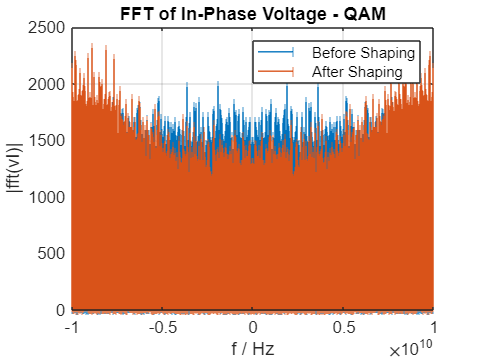


% Visualising pulse-shaped voltages
% stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_upsampled(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_shaped(1:10*SpS + filterSpan,1), "o-");
% title("Shaped In-Phase Voltage - QPSK");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After shaping");
% grid on
% hold off


% -------------------------------------------------------------------------

% FOR 16-QAM:
% Using RRC filter to shape vI and vQ

vI_QAM_shaped = upfirdn(vI_QAM, filterResponse, SpS, 1); vQ_QAM_shaped = upfirdn(vQ_QAM, filterResponse, SpS, 1); % Without AWGN
% vI_QAM_AWGN_shaped = upfirdn(real(vQAM_AWGN), filterResponse, SpS, 1); vQ_QAM_AWGN_shaped = upfirdn(imag(vQAM_AWGN), filterResponse, SpS, 1); % With AWGN

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QAM = fftshift(fft(vI_QAM_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QAM_shaped = fftshift(fft(vI_QAM_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);
% 
% stem(freqArr, abs(fft_vI_QAM), "|");
% hold on
% stem(freqArr_shaped, abs(fft_vI_QAM_shaped), "|");
% title("FFT of In-Phase Voltage - QAM");
% xlabel("f / Hz");
% ylabel("|fft(vI)|");
% legend("Before Shaping", "After Shaping");
% hold off
% grid on


% Visualising pulse-shaped voltages
% stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_upsampled(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_shaped(1:10*SpS + filterSpan,1), "o-");
% title("Shaped In-Phase Voltage - QAM");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After shaping");
% grid on
% hold off

bandwidth = 0.5*(1+rollOff)/T

bandwidth = 1.5000e+10

### IQ Modulation

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 0;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a contniuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % Laser output to be used with shaped signals

% Visualising output from laser
% plot(t(1:20), real(laserE(1:20)), "o-");
% title("Laser Output as a Continous Wave");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude / Vm^{-1}");
% grid on

% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

% Unshaped Signals
modOpticSigQPSK = IQModulatorModified(vI_QPSK_upsampled, vQ_QPSK_upsampled, laserE, Vpi);
modOpticSigQAM = IQModulatorModified(vI_QAM_upsampled, vQ_QAM_upsampled, laserE, Vpi);

% Shaped Signals
modOpticSigQPSK_shaped = IQModulatorModified(vI_QPSK_shaped, vQ_QPSK_shaped, laserE_shaped, Vpi);
modOpticSigQAM_shaped = IQModulatorModified(vI_QAM_shaped, vQ_QAM_shaped, laserE_shaped, Vpi); % Without AWGN

% Visualising modulated optical signals
% stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1)), "o-");
% hold on
% stairs(t(1:10*SpS), real(modOpticSigQAM(1:10*SpS,1)), "o-");
% title("Modulated Optical Signals")
% xlabel("Time/s")
% ylabel("Electric Field Amplitude / Vm^{-1}")
% legend("QPSK", "16QAM")
% grid on
% hold off

## Optical Channel

% Inserting CD
D = 17; % Group velocity dispersion in ps/nm/km
CLambda = 1550e-9; % Central wavelength of optical carrier in m
linkLength = 50e3; % Fibre link length in m

for i=1:2
    modOpticSigQPSK_CD(:,i) = CDInsertion(modOpticSigQPSK(:,i), SpS, Rs, D, CLambda, linkLength, 1);
end


### Optical Front-End

% Generating Local optical signal for coherent detection
% carr_freq = 3e8/(1550e-9); % Carrier frequency in ms-1
% freq_offset = 0; % LO signal frequency offset

Elo = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % LO signal with non-zero linewidth for unshaped signals
Elo_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % LO signal with non-zero linewidth for shaped signals
% Elo_shifted = LOFrequencyShift(Elo, freq_offset, T); % Frequency-shifted LO signal for unshaped information signal
% Elo_shaped_shifted = LOFrequencyShift(Elo_shaped, freq_offset, T); % Frequency-shifted LO signal for shaped information signal

% Visualising locally generated optical signal
% plot(t(1:20), real(Elo(1:20,1)), "-o");
% hold on
% plot(t(1:20), real(Elo_shifted(1:20,1)), "-o");
% title("Locally Generated Optical Signal");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude/ Vm^{-1}")
% legend("Ideal", "Frequency-Shifted")
% hold off
% grid on

% Visualising FFTs of original and frequency shifted LO laser signal
% fft_Elo = fftshift(fft(Elo(:,1))); % FFT of original LO signal
% fft_Elo_shifted = fftshift(fft(real(Elo_shifted(:,1)))); % FFT of frequency-shifted LO signal
% freqArr_Elo = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

% stem(freqArr_Elo, abs(fft_Elo), "|");
% hold on
% stem(freqArr_Elo, abs(fft_Elo_shifted), "|");
% title("FFT of LO Signals");
% xlabel("f / Hz");
% ylabel("|fft(Elo)|");
% legend("Matched signal", "Frequency-shifted signal");
% hold off
% grid on


% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

count=1;
for i=1:size(modOpticSigQPSK,2)
    % Unshaped Signals
    OpticFEOutQPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigQPSK(:,i), Elo, eta_ph, 1);
    OpticFEOutQPSK_CD(:,count:count+1) = OpticalFrontEnd(modOpticSigQPSK_CD(:,i), Elo, eta_ph, 1);
    OpticFEOutQAM(:,count:count+1) = OpticalFrontEnd(modOpticSigQAM(:,i), Elo, eta_ph, 1);
    
    % Shaped signals
    OpticFEOutQPSK_shaped(:,count:count+1) = OpticalFrontEnd(modOpticSigQPSK_shaped(:,i), Elo_shaped, eta_ph, 1);
    OpticFEOutQAM_shaped(:,count:count+1) = OpticalFrontEnd(modOpticSigQAM_shaped(:,i), Elo_shaped, eta_ph, 1); % Without AWGN

    count=count+2;
end

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components of the two polarizations
% QPSK
OpticFEOutQPSK_I = TIA_Gain*OpticFEOutQPSK(:,1:2:end); OpticFEOutQPSK_Q = TIA_Gain*OpticFEOutQPSK(:,2:2:end); % Unshaped 
OpticFEOutQPSK_CD_I = TIA_Gain*OpticFEOutQPSK_CD(:,1:2:end); OpticFEOutQPSK_CD_Q = TIA_Gain*OpticFEOutQPSK_CD(:,2:2:end); % Unshaped + CD

OpticFEOutQPSK_shaped_I = TIA_Gain*OpticFEOutQPSK_shaped(:,1:2:end); OpticFEOutQPSK_shaped_Q = TIA_Gain*OpticFEOutQPSK_shaped(:,2:2:end); % Shaped 

% 16-QAM
OpticFEOutQAM_I = TIA_Gain*OpticFEOutQAM(:,1:2:end); OpticFEOutQAM_Q = TIA_Gain*OpticFEOutQAM(:,2:2:end); % Unshaped
OpticFEOutQAM_shaped_I = TIA_Gain*OpticFEOutQAM_shaped(:,1:2:end); OpticFEOutQAM_shaped_Q = TIA_Gain*OpticFEOutQAM_shaped(:,2:2:end); % Shaped


## DSP

### Scaling and Downsampling

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
% scaleFactor=1;
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag/2;

% Cancelling the scaling factor and downsampling:

% % QPSK
voltageQPSK_I = OpticFEOutQPSK_I(1:SpS:end,:)/scaleFactor; voltageQPSK_Q = OpticFEOutQPSK_Q(1:SpS:end,:)/scaleFactor; % Unshaped 
voltageQPSK_CD_I = OpticFEOutQPSK_CD_I(1:SpS:end,:)/scaleFactor; voltageQPSK_CD_Q = OpticFEOutQPSK_CD_Q(1:SpS:end,:)/scaleFactor; % Unshaped + CD

voltageQPSK_shaped_I = upfirdn(OpticFEOutQPSK_shaped_I/scaleFactor, filterResponse, 1, SpS); voltageQPSK_shaped_I = voltageQPSK_shaped_I(filterSpan + 1:end - filterSpan,:); % Shaped 
voltageQPSK_shaped_Q = upfirdn(OpticFEOutQPSK_shaped_Q/scaleFactor, filterResponse, 1, SpS); voltageQPSK_shaped_Q = voltageQPSK_shaped_Q(filterSpan + 1:end - filterSpan,:); % Shaped 

% % 16-QAM
% voltageQAM_I = OpticFEOutQAM_I(1:SpS:end,:)/scaleFactor; voltageQAM_Q = OpticFEOutQAM_Q(1:SpS:end,:)/scaleFactor; % Unshaped 
% voltageQAM_shaped_I = upfirdn(OpticFEOutQAM_shaped_I/scaleFactor, filterResponse, 1, SpS); voltageQAM_shaped_I = voltageQAM_shaped_I(filterSpan + 1:end - filterSpan,:); % Shaped 
% voltageQAM_shaped_Q = upfirdn(OpticFEOutQAM_shaped_Q/scaleFactor, filterResponse, 1, SpS); voltageQAM_shaped_Q = voltageQAM_shaped_Q(filterSpan + 1:end - filterSpan,:); % Shaped 


### Adaptive Equalziation

% Without channel distortion
NTaps = 1001; NRemove = 350000; N1 = 100000; Mu = 0.0000001; Mu_p = 0;

trainSymbsQPSK = codedSymbolsQPSK; trainSymbsQPSK(2:2:end) = conj(trainSymbsQPSK(2:2:end));

% For QPSK:
% [equalizedSymbsQPSK, pQPSK, w11QPSK, w12QPSK, w21QPSK, w22QPSK, errQPSK] = AdapEqualizerAlamouti(voltageQPSK_I(:,1)+1i*voltageQPSK_Q, trainSymbsQPSK, 1, NTaps, Mu, Mu_p, N1, 'QPSK'); % Unshaped
[equalizedSymbsQPSK_CD, pQPSK_CD, w11QPSK_CD, w12QPSK_CD, w21QPSK_CD, w22QPSK_CD, errQPSK_CD] = AdapEqualizerAlamouti(voltageQPSK_CD_I(:,1)+1i*voltageQPSK_CD_Q, trainSymbsQPSK, SpS, NTaps, Mu, Mu_p, N1, 'QPSK'); % Unshaped + CD
% [equalizedSymbsQPSK_shaped, pQPSK_shaped, w11QPSK_shaped, w12QPSK_shaped, w21QPSK_shaped, w22QPSK_shaped] = AdapEqualizerAlamouti(voltageQPSK_shaped_I(:,1)+1i*voltageQPSK_shaped_Q(:,1), sourceSymbolsQPSK, SpS, NTaps, 0.0001, 0.0001, 100000, 'QPSK');

% For 16-QAM
% [equalizedSymbsQAM, pQAM, w11QAM, w12QAM, w21QAM, w22QAM] = AdapEqualizerAlamouti(OpticFEOutQAM_I(:,1)/scaleFactor+OpticFEOutQAM_Q(:,1)/scaleFactor, sourceSymbolsQAM, SpS, NTaps, 0.1, 0.1, 100000);
% [equalizedSymbsQAM_shaped, pQAM_shaped, w11QAM_shaped, w12QAM_shaped, w21QAM_shaped, w22QAM_shaped] = AdapEqualizerAlamouti(OpticFEOutQAM_shaped_I(:,1)/scaleFactor+OpticFEOutQAM_shaped_Q(:,1)/scaleFactor, sourceSymbolsQAM, SpS, NTaps, 0.1, 0.1, 100000);

% % Visualising evolution of filter coefficients
% plot([1:size(pQPSK)], w11QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{11}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], w12QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{12}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], w21QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{21}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], w22QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{22}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], pQPSK, '-');
% title("QPSK p variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(errQPSK(:,1))], abs(errQPSK(:,1)), '-');
% title("QPSK Odd Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(errQPSK(:,2))], abs(errQPSK(:,2)), '-');
% title("QPSK Even Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot(voltageQPSK_I+1i*voltageQPSK_Q, '+');
% hold on
% title("Symbol Distribution")
% plot(equalizedSymbsQPSK, '.');
% xlabel("Real")
% ylabel("Im")
% grid on
% hold off

% sourceSymbolsQPSK
% voltageQPSK_I+1i*voltageQPSK_Q
% equalizedSymbsQPSK

% ----------------------------------------------------------------------------
% With CD added

% Visualising evolution of filter coefficients
% plot([1:size(pQPSK_CD)], w11QPSK_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{11} with CD")

% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_CD)], w12QPSK_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{12} with CD")

Error using getByteStreamFromArray
Error during serialization

Error in matlab.internal.editor.figure.SerializedFigureState/serialize

Error in matlab.internal.editor.FigureProxy/createWebFigureSnapshot

Error in matlab.internal.editor.FigureManager

Error in matlab.internal.editor.FigureManager

Error in matlab.internal.editor.FigureManager.saveSnapshot

Error in matlab.internal.editor.FigureManager

Error in matlab.internal.editor.FigureManager.figureBeingCleared

Error in matlab.graphics.internal.clearNotify (

% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_CD)], w21QPSK_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{21} with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_CD)], w22QPSK_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{22} with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on

plot([1:size(pQPSK_CD)], pQPSK_CD, '-');
title("QPSK p variation with CD")
xlabel("Iteration")
ylabel("Value")
grid on

plot([1:size(errQPSK_CD(:,1))], abs(errQPSK_CD(:,1)), '-');
title("QPSK Odd Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

plot([1:size(errQPSK_CD(:,2))], abs(errQPSK_CD(:,2)), '-');
title("QPSK Even Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

plot(voltageQPSK_CD_I(:,1)+1i*voltageQPSK_CD_Q(:,1), '.');
hold on
title("Symbol Distribution")
plot(equalizedSymbsQPSK_CD(1:NRemove), '.');
plot(equalizedSymbsQPSK_CD(NRemove+1:end), '.');
plot(sourceSymbolsQPSK, '+', LineWidth=2);
xlabel("Real")
ylabel("Imaginary")
legend("Before Equalization", "Training", "DD")
grid on
hold off

## Receiver

### Decoding and Decision

% QPSK
% Without MIMO equalization:
% Unshaped
% testSymbolsQPSK = voltageQPSK_I(:,1) + 1i*voltageQPSK_Q(:,1);
% testSymbolsQPSK(2:2:end,1) = -1*conj(testSymbolsQPSK(2:2:end,1));
% testIntsQPSK = pskdemod(testSymbolsQPSK, 4, pi/4);
% testBitsQPSK = int2bit(testIntsQPSK, 2);
% biterr(testBitsQPSK, sourceBitsQPSK)

% Shaped
% testSymbolsQPSK_shaped = voltageQPSK_shaped_I(:,1) + 1i*voltageQPSK_shaped_Q(:,1);
% testSymbolsQPSK_shaped(2:2:end,1) = -1*conj(testSymbolsQPSK_shaped(2:2:end,1));
% testIntsQPSK_shaped = pskdemod(testSymbolsQPSK_shaped, 4, pi/4);
% testBitsQPSK_shaped = int2bit(testIntsQPSK_shaped, 2);
% biterr(testBitsQPSK_shaped, sourceBitsQPSK)

% With MIMO Eqaulization
% Unshaped
% After Equalization
% equalizedIntsQPSK = pskdemod(equalizedSymbsQPSK(NRemove/2+1:end,:), 4, pi/4);
% equalizedBitsQPSK = int2bit(equalizedIntsQPSK, 2);
% biterr(equalizedBitsQPSK, sourceBitsQPSK(NRemove+1:end))

% Unshaped + CD
% Before equalization
IntsQPSK_CD = pskdemod(voltageQPSK_CD_I+1i*voltageQPSK_CD_Q, 4, pi/4);
BitsQPSK_CD = int2bit(IntsQPSK_CD, 2);
[~, BERQPSK_CD_before] = biterr(BitsQPSK_CD(:,1), sourceBitsQPSK)

% After equalization
equalizedIntsQPSK_CD = pskdemod(equalizedSymbsQPSK_CD(NRemove+1:end,:), 4, pi/4);
equalizedBitsQPSK_CD = int2bit(equalizedIntsQPSK_CD, 2);
[~, BERQPSK_CD_after] = biterr(equalizedBitsQPSK_CD, sourceBitsQPSK(NRemove*2+1:end))

% Shaped
% equalizedIntsQPSK_shaped = pskdemod(equalizedSymbsQPSK_shaped(NRemove+1:end,:), 4, pi/4);
% equalizedBitsQPSK_shaped = int2bit(equalizedIntsQPSK_shaped, 2);
% biterr(equalizedBitsQPSK_shaped, sourceBitsQPSK(NRemove*2+1:end))

% --------------------------------------------------------------------------------------------

% 16QAM
% Without MIMO equalization:

% % Shaped
% testSymbolsQAM = voltageQAM_I(:,1) + 1i*voltageQAM_Q(:,1);
% testSymbolsQAM(2:2:end,1) = -1*conj(testSymbolsQAM(2:2:end,1));
% testIntsQAM = qamdemod(testSymbolsQAM, 16, UnitAveragePower=true);
% testBitsQAM = int2bit(testIntsQAM, 4);
% biterr(testBitsQAM, sourceBitsQAM)
% 
% % Unshaped
% testSymbolsQAM_shaped = voltageQAM_shaped_I(:,1) + 1i*voltageQAM_shaped_Q(:,1);
% testSymbolsQAM_shaped(2:2:end,1) = -1*conj(testSymbolsQAM_shaped(2:2:end,1));
% testIntsQAM_shaped = qamdemod(testSymbolsQAM_shaped, 16, UnitAveragePower=true);
% testBitsQAM_shaped = int2bit(testIntsQAM_shaped, 4);
% biterr(testBitsQAM_shaped, sourceBitsQAM)

% With MIMO Eqaulization
